## Week 1

clc; clear;

A = [
0,1,4;
1,3,3;
3,7,5;]

A =      0     1     4
     1     3     3
     3     7     5



B = [-4;-2;6]

B =     -4
    -2
     6



rref([A,B]), linsolve(A,B), A\B

ans =      1     0     0    19
     0     1     0    -8
     0     0     1     1


ans =    19.0000
   -8.0000
    1.0000


ans =    19.0000
   -8.0000
    1.0000



syms h x1 x2

Ma = [1 h;3 6]

$$Ma = \left(\begin{array}{cc} 1 & h\\ 3 & 6 \end{array}\right)$$

Mb = [4;8]

Mb =      4
     8



Mc = inv(Ma)

$$Mc = \left(\begin{array}{cc} -\frac{2}{h-2} & \frac{h}{3\,\left(h-2\right)}\\ \frac{1}{h-2} & -\frac{1}{3\,\left(h-2\right)} \end{array}\right)$$


Ma = [1 h;-2 4]

$$Ma = \left(\begin{array}{cc} 1 & h\\ -2 & 4 \end{array}\right)$$

rref(Ma)

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$


Mc = inv(Ma)

$$Mc = \left(\begin{array}{cc} \frac{2}{h+2} & -\frac{h}{2\,\left(h+2\right)}\\ \frac{1}{h+2} & \frac{1}{2\,\left(h+2\right)} \end{array}\right)$$


Ma = [1 3;-4 1*h]

$$Ma = \left(\begin{array}{cc} 1 & 3\\ -4 & h \end{array}\right)$$


Mc = inv(Ma)

$$Mc = \left(\begin{array}{cc} \frac{h}{h+12} & -\frac{3}{h+12}\\ \frac{4}{h+12} & \frac{1}{h+12} \end{array}\right)$$

## Section 1.2 tasks

clear;

% 45;
syms a_0 a_1 a_2
eq1 = a_0 + a_1*1 + a_2*1^2 == 11;
eq2 = a_0 + a_1*2 + a_2*2^2 == 16;
eq3 = a_0 + a_1*3 + a_2*3^2 == 19;

eqs = [eq1, eq2, eq3];

[A, b] = equationsToMatrix(eqs);

polvals = A\b;


$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 4\\ 0 & 1 & 0 & 8\\ 0 & 0 & 1 & -1 \end{array}\right)$$

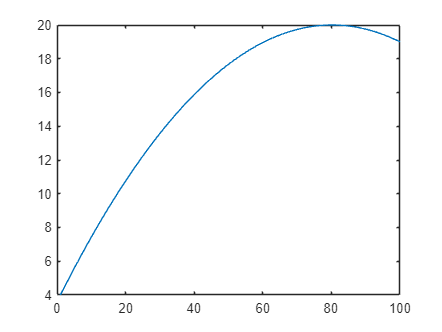

xs = linspace(0,5,100);

poly = polvals(1) + polvals(2).*xs + polvals(3).*xs.^2;

figure
plot(poly)

## Section 1.3 tasks

clear;

syms h

Ma = [
1 -2 4;
4 -3 1;
-2 7 h;
]

$$Ma = \left(\begin{array}{ccc} 1 & -2 & 4\\ 4 & -3 & 1\\ -2 & 7 & h \end{array}\right)$$


rref(Ma)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$


inv(Ma)*Ma

$$ans = \left(\begin{array}{ccc} \frac{8\,\left(h+14\right)}{5\,\left(h+17\right)}-\frac{4}{h+17}-\frac{3\,h+7}{5\,\left(h+17\right)} & \frac{14}{h+17}-\frac{6\,\left(h+14\right)}{5\,\left(h+17\right)}+\frac{2\,\left(3\,h+7\right)}{5\,\left(h+17\right)} & \frac{2\,\left(h+14\right)}{5\,\left(h+17\right)}-\frac{4\,\left(3\,h+7\right)}{5\,\left(h+17\right)}+\frac{2\,h}{h+17}\\ \frac{4\,\left(h+8\right)}{5\,\left(h+17\right)}-\frac{6}{h+17}-\frac{2\,\left(2\,h+1\right)}{5\,\left(h+17\right)} & \frac{21}{h+17}-\frac{3\,\left(h+8\right)}{5\,\left(h+17\right)}+\frac{4\,\left(2\,h+1\right)}{5\,\left(h+17\right)} & \frac{h+8}{5\,\left(h+17\right)}-\frac{8\,\left(2\,h+1\right)}{5\,\left(h+17\right)}+\frac{3\,h}{h+17}\\ 0 & 0 & \frac{17}{h+17}+\frac{h}{h+17} \end{array}\right)$$





Ma = [
1 -5 h;
0 1 -1;
-4 7 -5;
]

$$Ma = \left(\begin{array}{ccc} 1 & -5 & h\\ 0 & 1 & -1\\ -4 & 7 & -5 \end{array}\right)$$


rref(Ma)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$


inv(Ma)*Ma

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{1}{2\,h-9}+\frac{2\,\left(h-5\right)}{2\,h-9} & \sigma_{2}-\frac{5}{2\,h-9}-\frac{7\,\left(h-5\right)}{\sigma_{4}} & \frac{h}{2\,h-9}-\sigma_{2}+\frac{5\,\left(h-5\right)}{\sigma_{4}}\\ 0 & \sigma_{3}-\frac{13}{\sigma_{4}} & \sigma_{1}-\sigma_{3}-\frac{5}{\sigma_{4}}\\ 0 & 0 & \sigma_{1}-\frac{9}{2\,h-9} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,h}{2\,h-9}\\ \sigma_{2}=\frac{7\,h-25}{\sigma_{4}}\\ \sigma_{3}=\frac{4\,h-5}{\sigma_{4}}\\ \sigma_{4}=2\,\left(2\,h-9\right) \end{array}$$